# **INTRODUCCIÓN A LA CUANTIFICACIÓN ESCALAR Y VECTORIAL**

addpath('./datos')
addpath('./funciones')

[Afonso_8kHz, fs] = audioread('Afonso_8khz.wav');
[Gala_8kHz, fs] = audioread('Gala_8khz.wav');

## **TAREA 2: RELACIÓN SEÑAL-RUIDO DE CUANTIFICACIÓN**

Para el fichero Gala_8kHz.wav, con qmidriser() y qmidtread() de la tarea 1 con xsc=1:

- Obtened la SNR global, la SNR segmental y SNR por tramas. Representad junto a la señal original de forma análoga a “Ejemplo 2”. Utilizad n = 6 y L = 150. 

- Explicad las variaciones de la SNR por tramas. ¿En qué tramos de la señal es mayor? ¿Es posible que en alguna trama sea cero? 

`Midriser()`

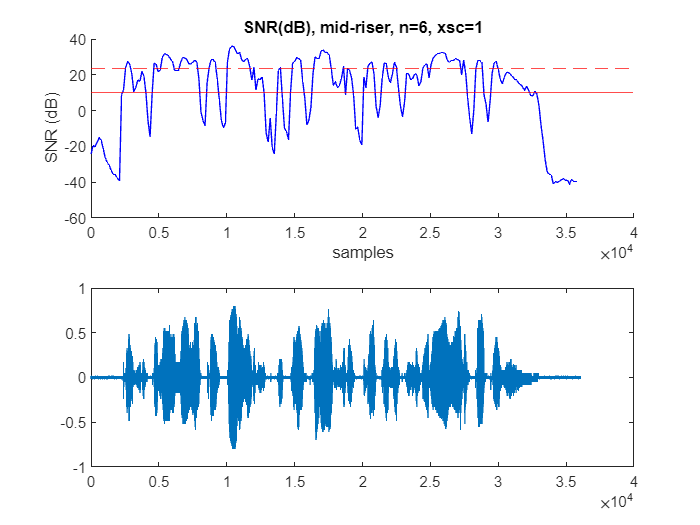

n = 6;
xsc=1;
[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_6b);
SNRq = SNR(Gala_8kHz,Gala_QMR_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-riser, n=6, xsc=1')
subplot 212
plot(Gala_QMR_6b)

`Midtread()`

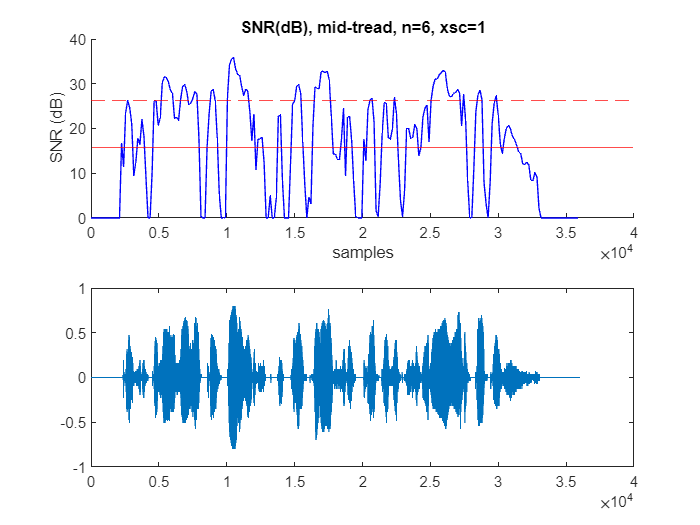

[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_6b);
SNRq = SNR(Gala_8kHz,Gala_QMT_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMT_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-tread, n=6, xsc=1')
subplot 212
plot(Gala_QMT_6b)

Repetid el apartado anterior para xsc=0.55 y xsc=0.3. Comparad y comentad los resultados. 

`Midriser()`

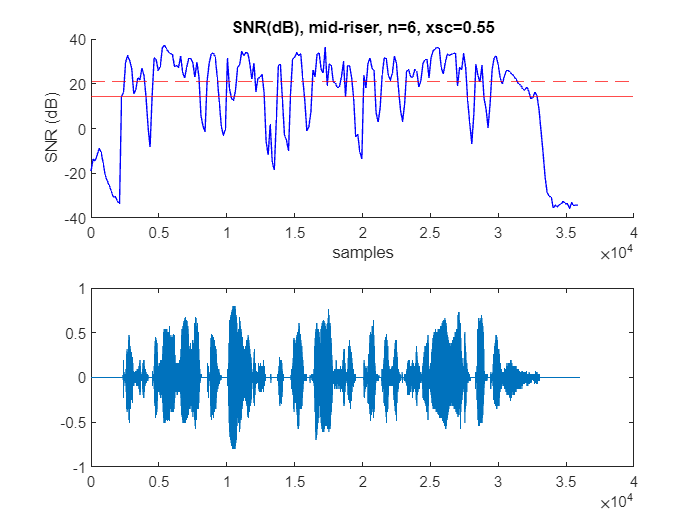

n = 6;
xsc=0.55;
[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_6b);
SNRq = SNR(Gala_8kHz,Gala_QMR_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-riser, n=6, xsc=0.55')
subplot 212
plot(Gala_QMT_6b)

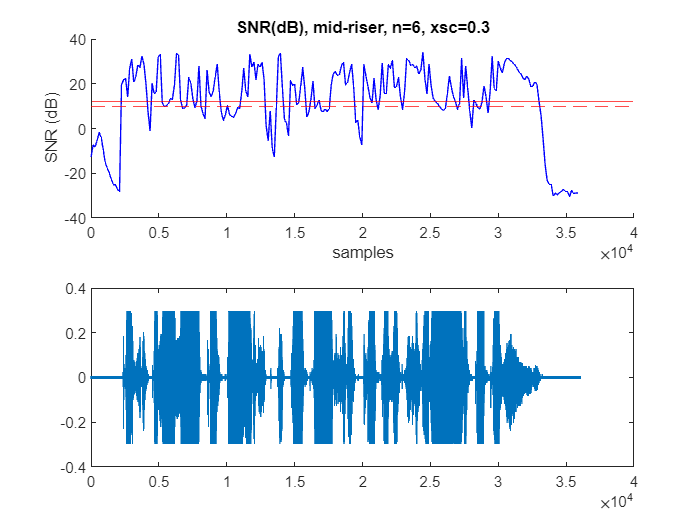


xsc=0.3;
[Gala_QMR_6b, e_Gala_QMR_6b] = qmidriser(Gala_8kHz, xsc, n);
sound(Gala_QMR_6b);
SNRq = SNR(Gala_8kHz,Gala_QMR_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMR_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-riser, n=6, xsc=0.3')
subplot 212
plot(Gala_QMR_6b)

`Midthread()`

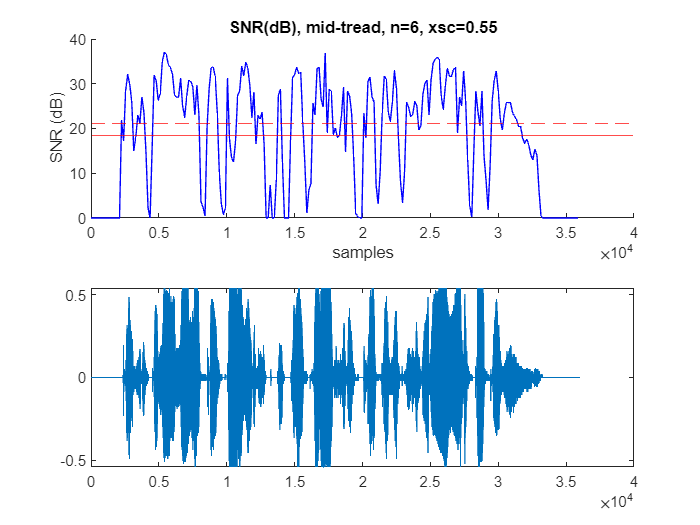

xsc=0.55;
[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_6b);
SNRq = SNR(Gala_8kHz,Gala_QMT_6b);
[SNRseg,SNRm,m] = SNRS(Gala_8kHz,Gala_QMT_6b,150);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-tread, n=6, xsc=0.55')
subplot 212
plot(Gala_QMT_6b)

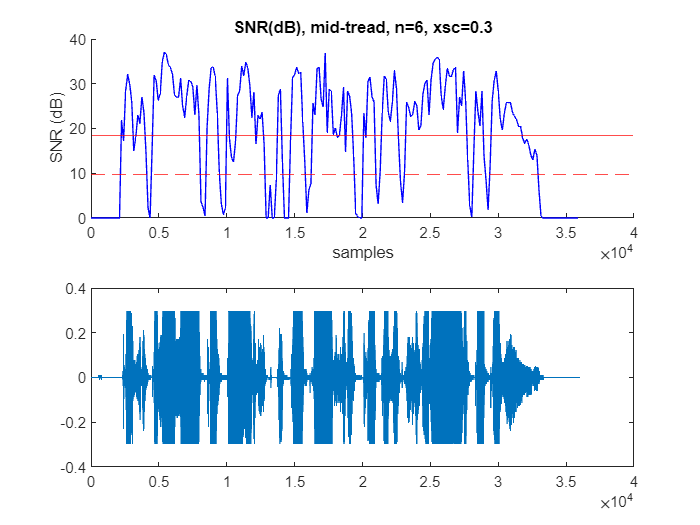


xsc=0.3;
[Gala_QMT_6b, e_Gala_QMT_6b] = qmidtread(Gala_8kHz, xsc, n);
sound(Gala_QMT_6b);
SNRq = SNR(Gala_8kHz,Gala_QMT_6b);

%plot (SNRm,SNRq,SNRseg)
figure
subplot 211
hold on
yline(SNRseg,'r')
yline(SNRq,'r--')
plot(m,SNRm,'b')
hold off

xlabel('samples')
ylabel('SNR (dB)')
title('SNR(dB), mid-tread, n=6, xsc=0.3')
subplot 212
plot(Gala_QMT_6b)

CÓMO GRAFICAAAAR

Para los ficheros Gala_8kHz.wav e Afonso_8kHz.wav, con n=1:8, xsc=1. 

- Obtened la SNR global en todos los casos, considerando qmidriser() y qmidtread(). 

- Representad resultados como en la gráfica de la diapositiva “Ejemplo 3”. 

`Midriser()`

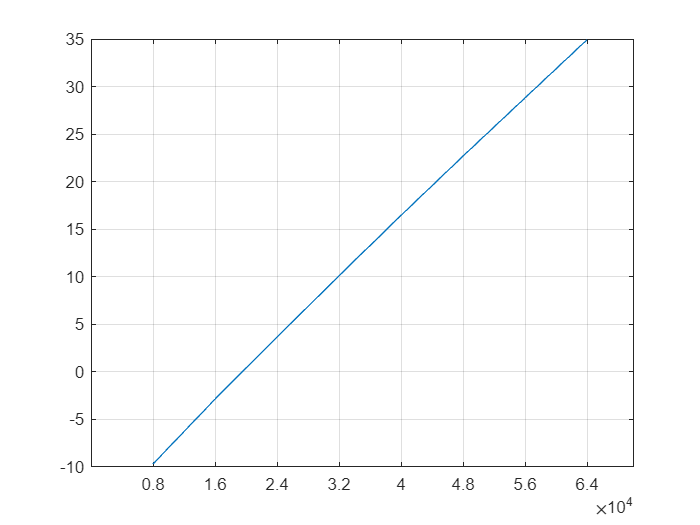

xsc=1;
fs=8*10^3;

for n=1:1:8
    [Afonso_QMR_nb, e_Afonso_QMR_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMR_nb);
    SNRq(n) = SNR(Afonso_8kHz,Afonso_QMR_nb);
end
n=1:1:8;
Rb = 8*10^3*n;
figure
plot(Rb,SNRq);
ax = gca; 
ax.XTick = Rb; 
grid

%plot(fs*1,graphics[1],'k',Rb); ax = gca; ax.XTick = Rb; grid

`Midtread()`

for n=1:1:8
    [Afonso_QMT_nb, e_Afonso_QMT_nb] = qmidtread(Afonso_8kHz, xsc, n);
    sound(Afonso_QMT_nb);
end
%plot(Rb,SNR1,'k',Rb); ax = gca; ax.XTick = Rb; grid

- Repetid para n=1:8, xsc=0.55 y xsc=0.3. En este apartado sólo con qmidriser(). 

- Explicad los resultados obtenidos. 

`Midriser()`

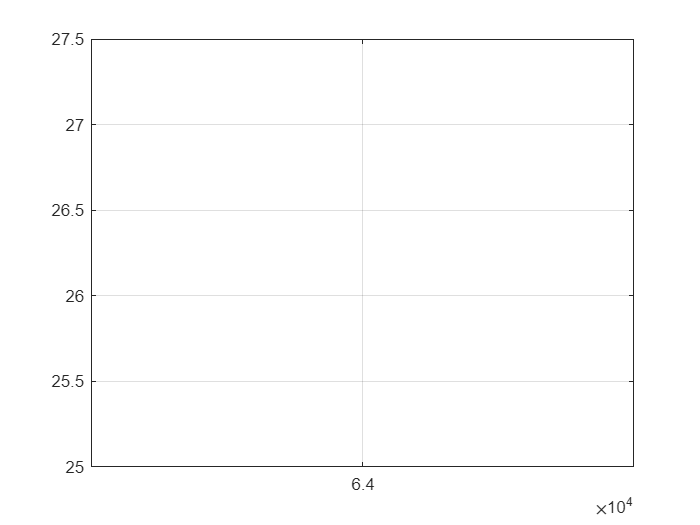

xsc=0.55;
for n=1:8
    [Afonso_QMR_nb, e_Afonso_QMR_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMR_nb);
    SNRq = SNR(Afonso_8kHz,Afonso_QMR_nb);
    [SNRseg,SNRm,m] = SNRS(Afonso_8kHz,Afonso_QMR_nb, 150);
end

Rb = 8*10^3*n;
figure
plot(Rb,SNRq);
ax = gca; 
ax.XTick = Rb; 
grid

   % hold on  


xsc=0.3;
for n=1:8
    [Afonso_QMR_nb, e_Afonso_QMR_nb] = qmidriser(Afonso_8kHz, xsc, n);
    sound(Afonso_QMR_nb);
end
